# Modelos del proceso

## Modelo Inicial

### Modelo de variables de estado:

A = -1/822.64;
B = 1/822.64;
C = 1.1861;
D = 0;

### Función de Transferencia:

[b,a] = ss2tf(A,B,C,D)

b =          0    0.0014


a =     1.0000    0.0012


k = 0.0014;
T = 0.0012;

%Función de Transferencia
P_1=(k)/((s+T))

P_1 =
 
    0.0014
  ----------
  s + 0.0012
 
Continuous-time transfer function.
Model Properties


## Modelo Identificación Experimental

### Función de Transferencia:

s=tf('s'); 
%POMTM
y0 = 22; yf = 74;
u0 = 0; uf = 100;
t_25 = 270; t_75 = 810;
delta_y = yf-y0;
delta_u = uf-u0;
%Ganancia
k=delta_y/delta_u;
%Constante de tiempo
T=0.9102*(t_75-t_25)

T = 491.5080

%Tiempo muerto
L=1.262*(t_25)-0.262*(t_75)

L = 128.5200


%Función de transferencia
P_2=(k*(exp(-L*s)))/((T*s+1))

P_2 =
 
                   0.52
  exp(-129*s) * -----------
                491.5 s + 1
 
Continuous-time transfer function.
Model Properties


### Modelo de Variables de Estado:

P_2=(k)/((T*s+1))

P_2 =
 
     0.52
  -----------
  491.5 s + 1
 
Continuous-time transfer function.
Model Properties



b=[0 k]

b =          0    0.5200


a=[T 1]

a =   491.5080    1.0000


[A,B,C,D] = tf2ss(b,a)

A = -0.0020

B = 1

C = 0.0011

D = 0


%Modelo de Variables de Estado
A = -0.0020;
B = 1;
C = 0.0111;
D = 0;

### Nueva Función de Transferencia:

[b,a] = ss2tf(A,B,C,D)

b =          0    0.0111


a =     1.0000    0.0020


k = 0.0111;
T = 0.0020;

%Función de Transferencia
P_3=(k)/((s+T))

P_3 =
 
   0.0111
  ---------
  s + 0.002
 
Continuous-time transfer function.
Model Properties


## Visualización de comportamiento

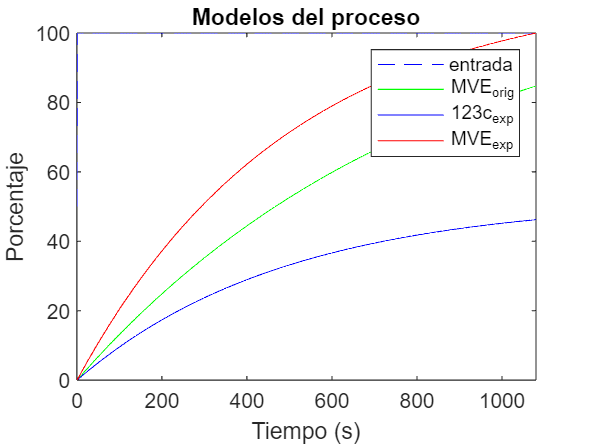

t=0:1:1080; %18min son 1080 segundos
u=100*heaviside(t);

p_1=lsim(P_1,u,t);
p_2=lsim(P_2,u,t);
p_3=lsim(P_3,u,t);

% Escalar la señal p_3 de 0 a 100%
p_3_min = min(p_3);
p_3_max = max(p_3);
p_3_scaled = 100 * (p_3 - p_3_min) / (p_3_max - p_3_min);

%Grafica del comportamiento

figure(1)
plot(t,u, 'b--', t, p_1, 'g', t, p_2, 'b', t, p_3_scaled,'r')
title('Modelos del proceso')
ylabel('Porcentaje')
xlabel('Tiempo (s)')
legend('entrada', 'MVE_orig', '123c_exp','MVE_exp')